bat_volt = 24;
gearbox_acc_lim = 20;

figure;
sim_time = 100;
upcl = [];
ugwl = [];
lpcl = [];
lgwl = [];
hl  = [];
gearbox_raios = 10:1:20;
for ratio = gearbox_raios
    robot.RL.lower_joint.joint.controller.ring_to_sun = ratio;
    robot.RL.upper_joint.joint.controller.ring_to_sun = ratio;
    out = sim('single_leg.slx', sim_time);
    jump_height = max(abs(out.height.Data));
    hl = [hl, jump_height];
    current = out.RL.leg.lower_joint_data.motor.current;
    T = current.Time;
    
    power_consumption = cumtrapz(current.Data) * sim_time / (60 * 60);
    lpcl = [lpcl, power_consumption(end)];

    subplot(4, 2, 1)
    plot(T, current.Data), hold on;
    title('Currnet') 
    ylabel('[A]') 
    
    subplot(4, 2, 2)
    plot(T, power_consumption), hold on;
    title('Power Consumption') 
    ylabel('[mAh]') 

    gearobx_acc_dat = abs([0 diff(out.RL.leg.lower_joint_data.motor.rad_s.Data)']);
    
    gearbox_wear = gearobx_acc_dat;
    gearbox_wear(gearbox_wear <= gearbox_acc_lim) = 0;
    gearbox_wear = cumtrapz(gearbox_wear);
    lgwl = [lgwl, gearbox_wear(end)];
    
    subplot(4, 2, 3)
    plot(T, gearobx_acc_dat), hold on;
    title('Motor Acceleration')
    ylabel('[$\frac{rad}{s^2}$]', "Interpreter", "latex")
    
    subplot(4, 2, 4)
    plot(T, gearbox_wear), hold on;
    title('Gearbox Wear')
    ylabel('[$s\frac{rad}{s}$]', "Interpreter", "latex")
    
    pwr_usage = power_consumption(end) * gearbox_wear(end);
    fprintf("Lower Joint\nPower consumption: %.2f\nGearbox wear %.2f\nPower x Wear %.2f\nHeight %.2f\nGear ratio %.2f\n\n", ...
        power_consumption(end), gearbox_wear(end), pwr_usage, jump_height, ratio);
    
    current = out.RL.leg.upper_jount_data.motor.current;
    T = current.Time;
    
    power_consumption = cumtrapz(current.Data) * sim_time / (60 * 60);
    upcl = [upcl, power_consumption(end)];
    
    
    subplot(4, 2, 5)
    plot(T, current.Data), hold on;
    title('Currnet') 
    ylabel('[A]') 
    
    subplot(4, 2, 6)
    plot(T, power_consumption), hold on;
    title('Power Consumption') 
    ylabel('[mAh]') 

    gearobx_acc_dat = abs([0 diff(out.RL.leg.lower_joint_data.motor.rad_s.Data)']);
    
    gearbox_wear = gearobx_acc_dat;
    gearbox_wear(gearbox_wear <= gearbox_acc_lim) = 0;
    gearbox_wear = cumtrapz(gearbox_wear);
    ugwl = [ugwl, gearbox_wear(end)];
    
    subplot(4, 2, 7)
    plot(T, gearobx_acc_dat), hold on;
    title('Motor Acceleration')
    ylabel('[$\frac{rad}{s^2}$]', "Interpreter", "latex")
    
    subplot(4, 2, 8)
    plot(T, gearbox_wear), hold on;
    title('Gearbox Wear')
    ylabel('[$\frac{rad}{s}$]', "Interpreter", "latex")
    
    pwr_usage = power_consumption(end) * gearbox_wear(end);
    fprintf("Upper Joint\nPower consumption: %.2f\nGearbox wear %.2f\nPower x Wear %.2f\nHeight %.2f\nGear ratio %.2f\n\n\n", ...
        power_consumption(end), gearbox_wear(end), pwr_usage, jump_height, ratio);
end

Lower Joint
Power consumption: 1263.79
Gearbox wear 0.00
Power x Wear 0.00
Height 0.50
Gear ratio 10.00



Upper Joint
Power consumption: 1318.89
Gearbox wear 0.00
Power x Wear 0.00
Height 0.50
Gear ratio 10.00




Lower Joint
Power consumption: 635.54
Gearbox wear 0.00
Power x Wear 0.00
Height 0.55
Gear ratio 11.00



Upper Joint
Power consumption: 696.29
Gearbox wear 0.00
Power x Wear 0.00
Height 0.55
Gear ratio 11.00




Lower Joint
Power consumption: 386.10
Gearbox wear 0.00
Power x Wear 0.00
Height 0.57
Gear ratio 12.00



Upper Joint
Power consumption: 468.12
Gearbox wear 0.00
Power x Wear 0.00
Height 0.57
Gear ratio 12.00




Lower Joint
Power consumption: 529.95
Gearbox wear 0.00
Power x Wear 0.00
Height 0.59
Gear ratio 13.00



Upper Joint
Power consumption: 607.31
Gearbox wear 0.00
Power x Wear 0.00
Height 0.59
Gear ratio 13.00




Lower Joint
Power consumption: 369.21
Gearbox wear 0.00
Power x Wear 0.00
Height 0.60
Gear ratio 14.00



Upper Joint
Power consumption: 441.62
Gearbox wear 0.00
Power x Wear 0.00
Height 0.60
Gear ratio 14.00




Lower Joint
Power consumption: 889.98
Gearbox wear 65.84
Power x Wear 58595.99
Height 0.61
Gear ratio 15.00



Upper Joint
Power consumption: 973.31
Gearbox wear 65.84
Power x Wear 64081.91
Height 0.61
Gear ratio 15.00




Lower Joint
Power consumption: 467.33
Gearbox wear 119.50
Power x Wear 55845.00
Height 0.61
Gear ratio 16.00



Upper Joint
Power consumption: 546.41
Gearbox wear 119.50
Power x Wear 65294.67
Height 0.61
Gear ratio 16.00




Lower Joint
Power consumption: 298.87
Gearbox wear 155.32
Power x Wear 46421.99
Height 0.62
Gear ratio 17.00



Upper Joint
Power consumption: 356.48
Gearbox wear 155.32
Power x Wear 55369.89
Height 0.62
Gear ratio 17.00




Lower Joint
Power consumption: 368.36
Gearbox wear 200.87
Power x Wear 73992.04
Height 0.63
Gear ratio 18.00



Upper Joint
Power consumption: 411.12
Gearbox wear 200.87
Power x Wear 82581.91
Height 0.63
Gear ratio 18.00




Lower Joint
Power consumption: 300.03
Gearbox wear 244.59
Power x Wear 73383.82
Height 0.65
Gear ratio 19.00



Upper Joint
Power consumption: 346.43
Gearbox wear 244.59
Power x Wear 84732.66
Height 0.65
Gear ratio 19.00




Lower Joint
Power consumption: 371.22
Gearbox wear 297.07
Power x Wear 110279.60
Height 0.65
Gear ratio 20.00



Upper Joint
Power consumption: 417.63
Gearbox wear 297.07
Power x Wear 124067.34
Height 0.65
Gear ratio 20.00




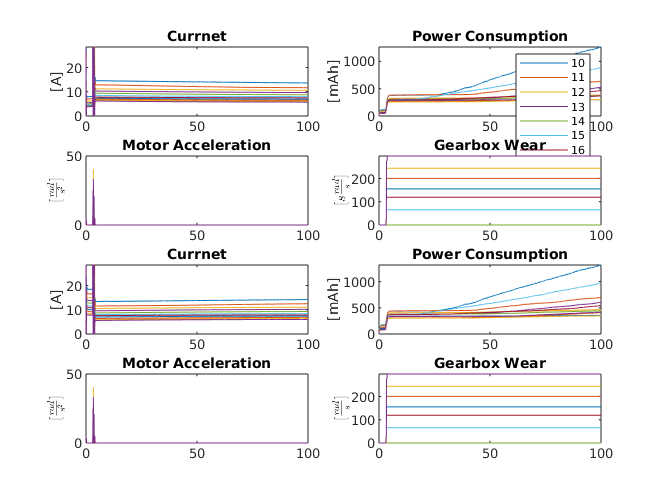


subplot(4, 2, 2)
legend(string(gearbox_raios), "Location", "southeast")

hold off;

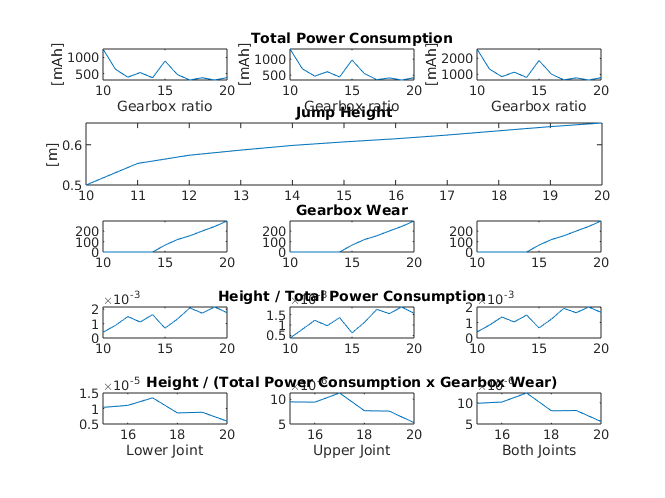

figure;
subplot(5, 3, 1)
plot(gearbox_raios, lpcl)
ylabel('[mAh]') 
xlabel("Gearbox ratio")

subplot(5, 3, [4, 5, 6])
plot(gearbox_raios, hl)
title('Jump Height') 
ylabel('[m]') 

subplot(5, 3, 7)
plot(gearbox_raios, lgwl)

subplot(5, 3, 10)
plot(gearbox_raios, hl ./ lpcl)

subplot(5, 3, 13)
plot(gearbox_raios, hl ./ lpcl ./ lgwl)
xlabel("Lower Joint")

subplot(5, 3, 2)
plot(gearbox_raios, upcl)
title('Total Power Consumption') 
ylabel('[mAh]') 
xlabel("Gearbox ratio")

subplot(5, 3, 8)
plot(gearbox_raios, ugwl)
title('Gearbox Wear') 

subplot(5, 3, 11)
plot(gearbox_raios, hl ./ upcl)
title('Height / Total Power Consumption') 

subplot(5, 3, 14)
plot(gearbox_raios, hl ./ upcl ./ ugwl)
title('Height / (Total Power Consumption x Gearbox Wear)') 
xlabel("Upper Joint")



subplot(5, 3, 3)
plot(gearbox_raios, upcl + lpcl)
ylabel('[mAh]') 
xlabel("Gearbox ratio")

subplot(5, 3, 9)
plot(gearbox_raios, (ugwl + lgwl) ./ 2)

subplot(5, 3, 12)
plot(gearbox_raios, ((hl ./ upcl) + (hl ./ lpcl)) ./ 2)

subplot(5, 3, 15)
plot(gearbox_raios, ((hl ./ upcl ./ ugwl) + (hl ./ lpcl ./ lgwl)) ./ 2)
xlabel("Both Joints")

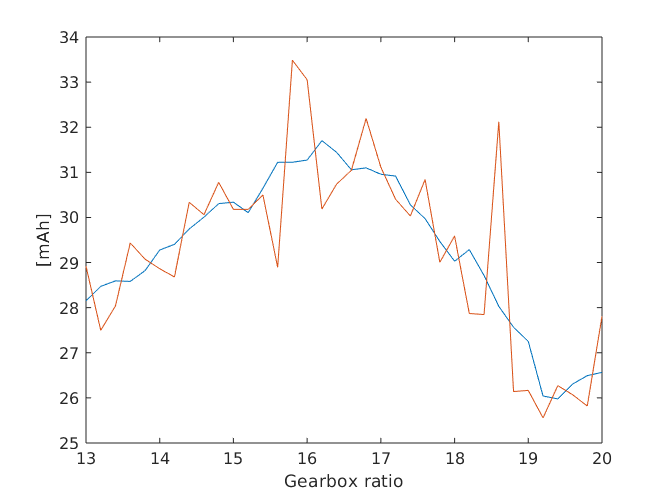

figure
plot(gearbox_raios, movmean(lpcl, 5)), hold on;
plot(gearbox_raios, lpcl), hold off;
% grid on;
ylabel('[mAh]') 
xlabel("Gearbox ratio")

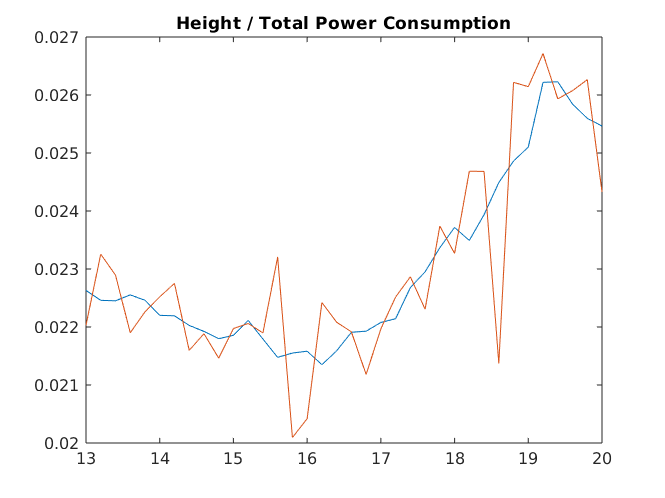


figure;
plot(gearbox_raios, hl ./ movmean(lpcl, 5)), hold on;
plot(gearbox_raios, hl ./ lpcl), hold off;
title('Height / Total Power Consumption') 